# Calcalate generation features in 2019

The program is used to calculate generation features of the aggregated units in NYAM, such as max power,. min power, and max ramp rate.

## Import the RGGI generation data

% Import hourly generation data of generators in RGGI database in the 2019 whole year
genFileDir = "D:\EERL\ny_academic_model\data\EPA_AMPD\2019\";
genFileName = "emission*.csv";
genDataStore = fileDatastore(genFileDir + genFileName, "ReadFcn", @importGenerationData, "UniformRead", true);
genAll = readall(genDataStore);

## Import RGGI to NYCA reference table

% Import the reference table from RGGI to NYISO NYCA database
generatorCombiner = importRefTable("D:\EERL\ny_academic_model\SimpleNet\Data\RGGI2NYCA2019NoAgg.xlsx");

% Create arrays of key features
NYISONames = unique(generatorCombiner.NYISOName);
PTIDs = unique(generatorCombiner.PTID);
unitTypes = unique(generatorCombiner.UnitType);
fuelTypes = unique(generatorCombiner.FuelType);
Zones = unique(generatorCombiner.Zone);

## Group summary of nameplate capacity in NYCA database

% Group summary of nameplate capacity by unit type and fuel type
unitFuelTypeSummary = groupsummary(generatorCombiner, ["UnitType", "FuelType"] , "sum", ["NamePlateRatingMW", "GrossLoadMWh"]);
total_count = sum(unitFuelTypeSummary.GroupCount);
total_cap = sum(unitFuelTypeSummary.sum_NamePlateRatingMW);
total_gen = sum(unitFuelTypeSummary.sum_GrossLoadMWh);
unitFuelTypeSummary.capPer = unitFuelTypeSummary.sum_NamePlateRatingMW/total_cap;
unitFuelTypeSummary.genPer = unitFuelTypeSummary.sum_GrossLoadMWh/total_gen;
unitFuelTypeSummary.Properties.VariableNames = ["unitType", "fuelType", "Count", "totalCapacity", "totalGeneration", "capPercent", "genPercent"]

unitFuelTypeSummary = 9×7 table
         unitType          fuelType      Count    totalCapacity    totalGeneration    capPercent    genPercent
    __________________    ___________    _____    _____________    _______________    __________    __________

    Combined Cycle        Natural Gas     59          18154           3.718e+07         0.52871        0.79628
    Combustion Turbine    Fuel Oil         8          500.9               21660        0.014588     0.00046388
    Combustion Turbine    Natural Gas     30         1247.8          1.1198e+06        0.036341       0.023983
    Jet Engine            Fuel Oil        11            621               36080        0.018086     0.00077272
    Jet Engine            Kerosene        25         1176.5    

unitTypeSummary = groupsummary(unitFuelTypeSummary, "unitType", "sum", ["Count","totalCapacity", "capPercent", "totalGeneration", "genPercent"]);
unitTypeSummary = removevars(unitTypeSummary, "GroupCount");
unitTypeSummary.Properties.VariableNames = ["unitType", "Count", "totalCapacity", "capPercent", "totalGeneration", "genPercent"]

unitTypeSummary = 4×6 table
         unitType         Count    totalCapacity    capPercent    totalGeneration    genPercent
    __________________    _____    _____________    __________    _______________    __________

    Combined Cycle         59          18154          0.52871        3.718e+07         0.79628 
    Combustion Turbine     38         1748.7         0.050929       1.1414e+06        0.024446 
    Jet Engine             39         1946.4         0.056687       1.9104e+05       0.0040916 
    Steam Turbine          31          12487          0.36368       8.1796e+06         0.17518 


fuelTypeSummary = groupsummary(unitFuelTypeSummary, "fuelType", "sum", ["Count","totalCapacity", "capPercent", "totalGeneration", "genPercent"]);
fuelTypeSummary = removevars(fuelTypeSummary, "GroupCount");
fuelTypeSummary.Properties.VariableNames = ["fuelType", "Count", "totalCapacity", "capPercent", "totalGeneration", "genPercent"]

fuelTypeSummary = 4×6 table
     fuelType      Count    totalCapacity    capPercent    totalGeneration    genPercent
    ___________    _____    _____________    __________    _______________    __________

    Coal              2         810.4         0.023602       4.7214e+05         0.010112
    Fuel Oil         32        7896.5          0.22998       2.8215e+06         0.060428
    Kerosene         25        1176.5         0.034264            26821       0.00057443
    Natural Gas     108         24453          0.71216       4.3371e+07          0.92889


## Combine the generation table with the reference table

% Combine the RGGI database with the NYCA database
% Join tables
genAllJoint = innerjoin(genAll,generatorCombiner,'Keys',{'FacilityName','FacilityID','UnitID'}, 'LeftVariables', {'FacilityName',...
    'FacilityID', 'UnitID', 'Date', 'Hour', 'GrossLoadMW', 'HeatInputMMBtu'}, "RightVariables", {'NYISOName', 'PTID', 'Zone', 'UnitType', 'FuelType', 'Combined'});

## Calculate generation features

% Define arrays to record NYISO generators' parameter
maxPower = zeros(size(NYISONames));
minPower = zeros(size(NYISONames));
maxHeat = zeros(size(NYISONames));
minHeat = zeros(size(NYISONames));
maxRampUp = zeros(size(NYISONames));
maxRampDown = zeros(size(NYISONames));
HeatRateLM = zeros(size(NYISONames, 1), 2);
HeatRateR2 = zeros(size(NYISONames));
hourlyGenFilteredTables = cell(size(NYISONames));

for i=1:length(NYISONames)
    genName = NYISONames(i);
    genSet = genAllJoint(genAllJoint.NYISOName == genName, :);
    hourlyGen = groupsummary(genSet, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu"]);
    rampRate = hourlyGen.sum_GrossLoadMW(2:end) - hourlyGen.sum_GrossLoadMW(1:end-1);
    hourlyGen.RampRate = [0; rampRate];
    hourlyGenNZ = hourlyGen(hourlyGen.sum_GrossLoadMW > 0, :);
    lowPercent = 10;
    highPercent = 100;
    [genOutIdx,genPer10,genMax,genMedian] = isoutlier(hourlyGenNZ.sum_GrossLoadMW,"percentiles", [lowPercent, highPercent]);
    [heatOutIdx,heatPer10,heatMax,heatMedian] = isoutlier(hourlyGenNZ.sum_HeatInputMMBtu,"percentiles", [lowPercent, highPercent]);
    genHeatOutIdx = genOutIdx|heatOutIdx;
    hourlyGenNZFiltered = hourlyGenNZ(~genHeatOutIdx, :);
    genHeatLM = fitlm(hourlyGenNZFiltered, "sum_HeatInputMMBtu ~ 1 + sum_GrossLoadMW");
    HeatRateR2(i) = genHeatLM.Rsquared.Adjusted;
    HeatRateLM(i, :) = genHeatLM.Coefficients.Estimate.';
    maxPower(i) = genMax;
    minPower(i) = genPer10;
    maxRampUp(i) = max(hourlyGenNZFiltered.RampRate);
    maxRampDown(i) = min(hourlyGenNZFiltered.RampRate);
    hourlyGenFilteredTables{i} = hourlyGenNZFiltered;
end

% Combine generator parameters into one summary table
maxRamp60 = (maxRampUp + abs(maxRampDown))/2;
maxRamp30 = maxRamp60/2;
maxRamp10 = maxRamp30/3;
maxRampAgc = maxRamp10/10;
paramSummary = table(NYISONames, maxPower, minPower, maxRampAgc, maxRamp10, maxRamp30);

genComNoDup = generatorCombiner(generatorCombiner.Combined == "0", ["NYISOName", "Zone", "UnitType", "FuelType", "NamePlateRatingMW", "CapabilitySummerMW", "CapabilityWinterMW"]);
genComDup = generatorCombiner(generatorCombiner.Combined == "1", ["NYISOName", "Zone", "UnitType", "FuelType", "NamePlateRatingMW", "CapabilitySummerMW", "CapabilityWinterMW"]);
genComDupRed = unique(genComDup, 'rows');
genComRed = [genComNoDup; genComDupRed];

% Add generator information to the generator summary table
paramSummaryJoint = join(paramSummary,genComRed,'LeftKeys',{'NYISONames'},'RightKeys',{'NYISOName'}, "LeftVariables", {'maxPower', 'minPower', 'maxRampAgc','maxRamp10','maxRamp30'} ...
    , "RightVariables",{'NYISOName', 'Zone', 'NamePlateRatingMW', 'CapabilitySummerMW', 'CapabilityWinterMW','UnitType', 'FuelType'})

paramSummaryJoint = 141×12 table
    maxPower    minPower    maxRampAgc    maxRamp10    maxRamp30            NYISOName            Zone    NamePlateRatingMW    CapabilitySummerMW    CapabilityWinterMW       UnitType        FuelType  
    ________    ________    __________    _________    _________    _________________________    ____    _________________    __________________    __________________    ______________    ___________

       66           13       0.54167       5.4167        16.25      Allegany                      B               67                 61.4                  63.

busArray = [1; 2; 3; 4; 5; 6; 7; 8; 9; 10; 11];
zoneArray = categorical(["A"; "B"; "C"; "D"; "E"; "F"; "G"; "H"; "I"; "J"; "K"]);
mpcGen = zeros(size(NYISONames, 1), 21);

for i=1:size(NYISONames, 1)
    for j=1:size(busArray, 1)
        if zoneArray(j) == paramSummaryJoint.Zone(i)        
            busID = busArray(j);
        end
    end
    mpcGen(i, 1) = busID; % bus ID
end
mpcGen(:, 2) = zeros(size(NYISONames)); % Pg
mpcGen(:, 3) = zeros(size(NYISONames)); % Qg
mpcGen(:, 4) = 9999*ones(size(NYISONames)); % Qmax
mpcGen(:, 5) = -9999*ones(size(NYISONames)); % Qmin
mpcGen(:, 6) = 1.00*ones(size(NYISONames)); % Vg
mpcGen(:, 7) = 100*ones(size(NYISONames)); % mBase
mpcGen(:, 8) = 1*ones(size(NYISONames)); % Status
mpcGen(:, 9) = paramSummaryJoint.maxPower; % Pmax
mpcGen(:, 10) = paramSummaryJoint.minPower; % Pmin
% 11-16 all zeros: Pc1, Pc2, Qc1min, Qc1max, Qc2min, Qc2max
mpcGen(:, 17) = paramSummaryJoint.maxRampAgc; % ramp_agc
mpcGen(:, 18) = paramSummaryJoint.maxRamp10; % ramp_10
mpcGen(:, 19) = paramSummaryJoint.maxRamp30; % ramp_30
% 20-21 all zeros: ramp_q, apf
mpcGen

mpcGen =             2            0            0         9999        -9999            1          100            1           66           13            0            0            0            0            0            0      0.54167       5.4167        16.25            0            0
           10            0            0         9999        -9999            1          100            1          349           96            0            0            0            0            0            0         2.85         28.5         85.5            0            0
           10            0            0         9999        -9999            1          100            1          539            1            0            0            0            0            0            0       3.1083       31.083        93.25            0            0
           10            0            0         9999        -9999            1          100            1          153            1            0            0            0

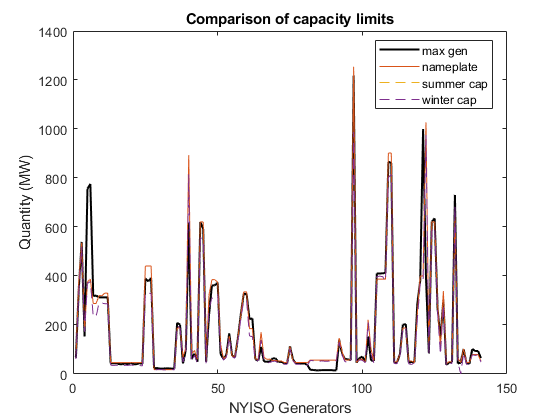

figure;
plot(paramSummaryJoint.maxPower, 'k', "LineWidth",1.5);
hold on;
plot(paramSummaryJoint.NamePlateRatingMW);
plot(paramSummaryJoint.CapabilitySummerMW, '--');
plot(paramSummaryJoint.CapabilitySummerMW, '--');
% plot(paramSummaryJoint.CRISSummerMW, '-.');
% plot(paramSummaryJoint.CRISWinterMW, '-.');
hold off;
legend(["max gen", "nameplate", "summer cap", "winter cap"], "Location","best");
xlabel("NYISO Generators");
ylabel("Quantity (MW)");
title("Comparison of capacity limits");

badFitIdx = HeatRateR2 < 0.5;
badFitNum = nnz(badFitIdx)

badFitNum =     14


badFitNames = NYISONames(badFitIdx);
badFitFilteredTables = hourlyGenFilteredTables(badFitIdx);
badFitLMs = HeatRateLM(badFitIdx, :);
badFitR2s = HeatRateR2(badFitIdx);

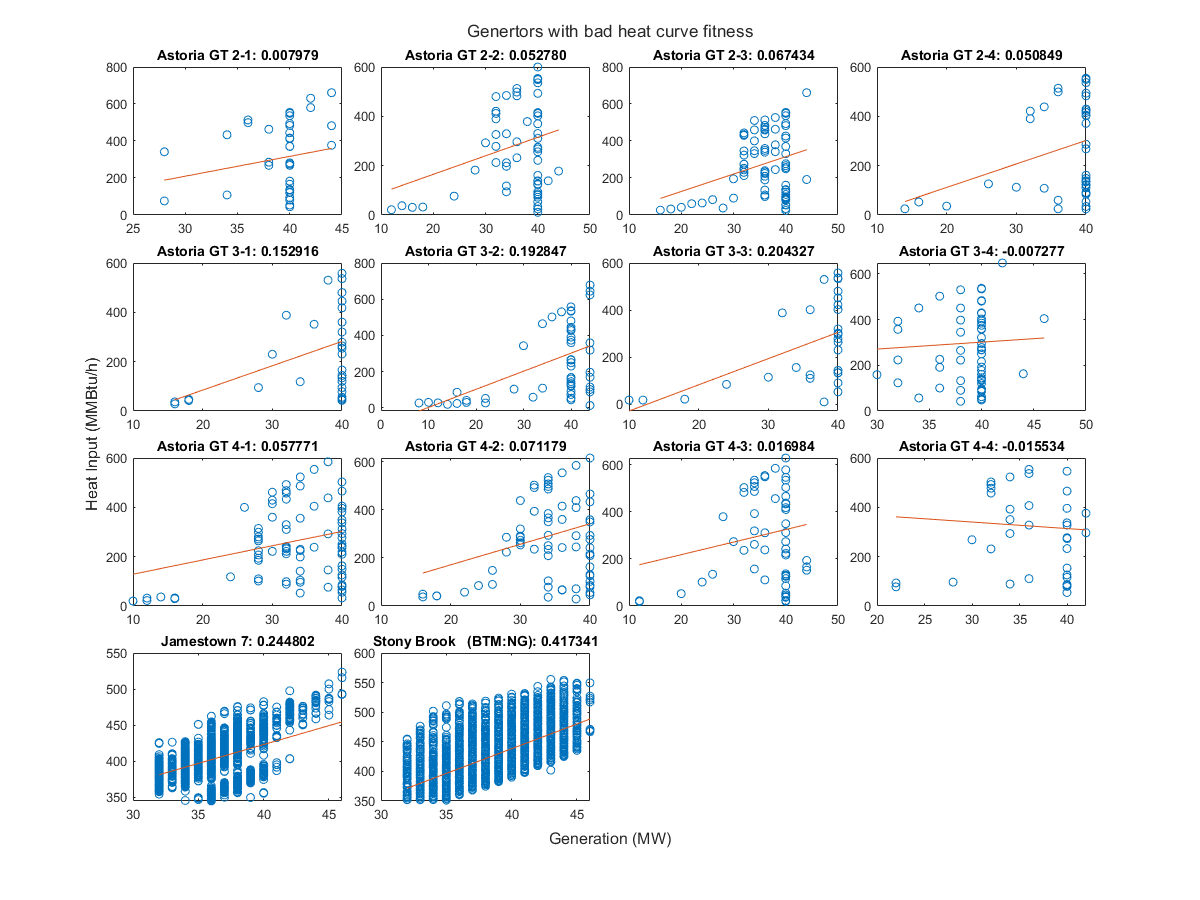

t = tiledlayout(4, 4, "TileSpacing","compact");
for n=1:badFitNum
    nexttile;
    badFitName = badFitNames(n);
    badFitR2 = badFitR2s(n);
    badFitTable = badFitFilteredTables{n};
    badFitLM = badFitLMs(n, :);
    scatter(badFitTable.sum_GrossLoadMW, badFitTable.sum_HeatInputMMBtu)
    hold on;
    plot(badFitTable.sum_GrossLoadMW, badFitLM(1) + badFitTable.sum_GrossLoadMW*badFitLM(2))
    hold off; box on;
    txt = sprintf("%s: %f", badFitName, badFitR2);
    title(txt);
end
xlabel(t, "Generation (MW)");
ylabel(t, "Heat Input (MMBtu/h)");
title(t, "Genertors with bad heat curve fitness");
set(gcf, "Position", [50, 50, 1200, 900]);